% 从excel里面读取数据
filename = '../data/附件二：会员信息数据.xlsx';
cNode = 835;  % 送货节点数量（不包括快递公司）

% 读取客户的坐标和需求量
data = readcell(filename, 'Range', sprintf('B2:E%d', cNode+1));  % 使用 readcell 读取包含字符串的单元格
GPS = data(:, 1);
task = cell2mat(data(:, 2));
time = data(:, 3);
conf = cell2mat(data(:, 4));

% 将GPS字符串拆分为x和y坐标
coords = cellfun(@(x) sscanf(x, '%f %f')', GPS, 'UniformOutput', false);
coords = cell2mat(coords);

% 分离x和y坐标
x = coords(:, 2);
y = coords(:, 1);

% 现在你可以使用x和y坐标进行绘图或其他操作

画图

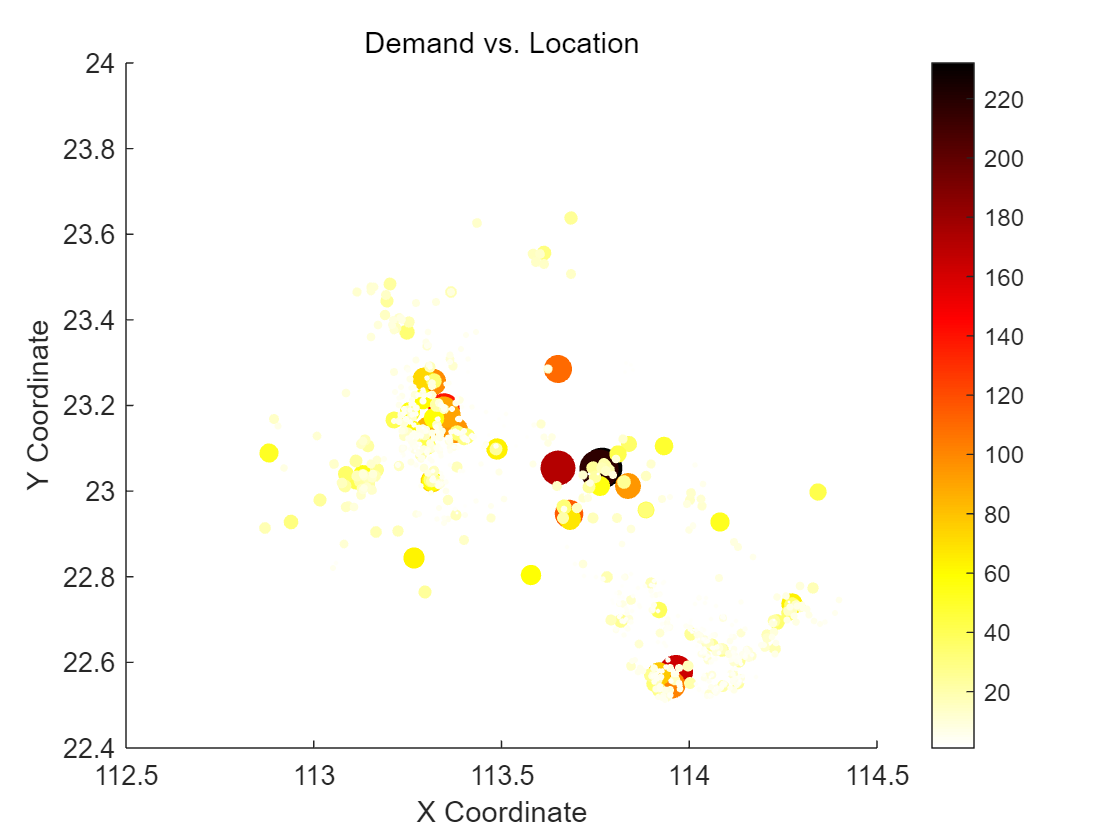

% 绘制散点图，点的大小与需求（price）成正比，颜色与需求成比例
scatter(x, y, task, task, 'filled')
% 添加颜色条，以便参照需求值的颜色变化
colorbar;
colormap(flipud(hot)); % 反转 'hot' 颜色图 % 您可以更改颜色图，如 'jet', 'hsv', 'hot' 等
% 设置横轴和纵轴的显示范围
xlim([112.5 114.5]) % 可以替换为具体范围，如 [110 115]
ylim([22.4 24]) % 可以替换为具体范围，如 [20 25]
% 添加标题和标签
title('Demand vs. Location')
xlabel('X Coordinate')
ylabel('Y Coordinate')